# Test Bioluminescence (BLT)

close all
clear variables
clc

## display properties

set(0, 'DefaultAxesFontname', 'Arial CE');
font_size = 16;
set(0, 'DefaultAxesFontsize', font_size);
set(0, 'defaulttextfontname', 'Arial CE');
set(0, 'defaulttextfontsize', font_size);
set(0, 'defaultfigurecolor', 'w');

## BODY

## set the 'nirfasterroot' as current folder

cd(nirfasterroot);

## test BLT on 2D mesh:

% forward data 2D, spectral

mesh = load_mesh('circle2000_86_spec');

Moving Sources
Fixed detectors
Calculating detectors integration functions



% add bioluminescence blob
blob.x = 0;
blob.y = -10;
blob.r = 10;
blob.region = 1;
% anomaly mesh
mesh_anom = add_blob(mesh,blob);

Number of nodes modified = 90


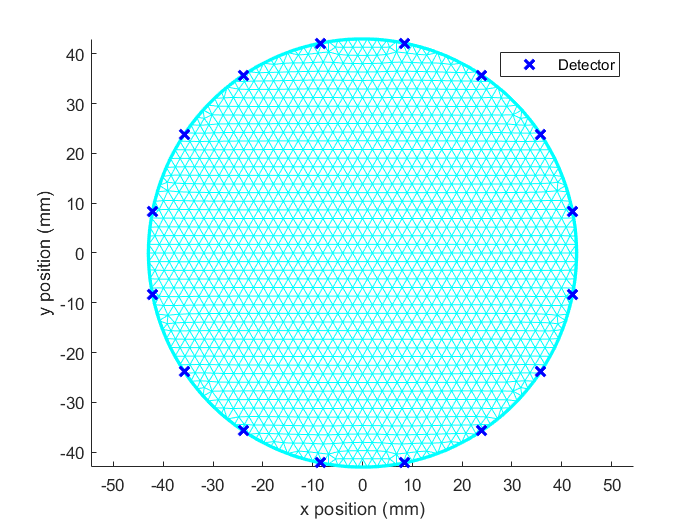

% make the mesh BLT
mesh.blt = mesh_anom.region;

% plot mesh with detectors only
mesh_anom = rmfield(mesh_anom,'source');
plotmesh_fiducials(mesh_anom);

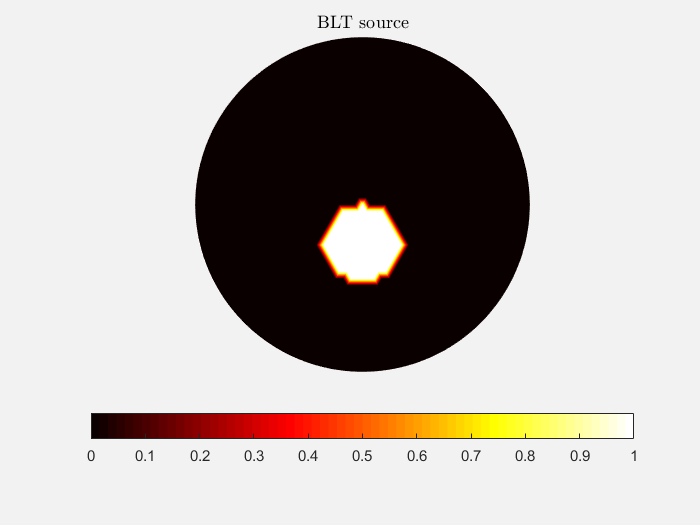


% show blob - the BLT source
plotimage(mesh,mesh.blt);
title('BLT source','Interpreter','latex');

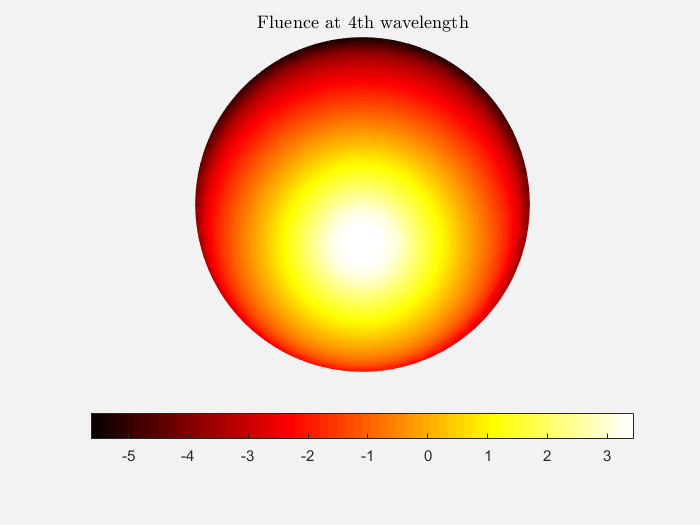


% forward data
data_BLT = femdata_BLT(mesh);

plotimage(mesh,log(abs(data_BLT.phi(:,4))));
title('Fluence at 4th wavelength','Interpreter','latex');

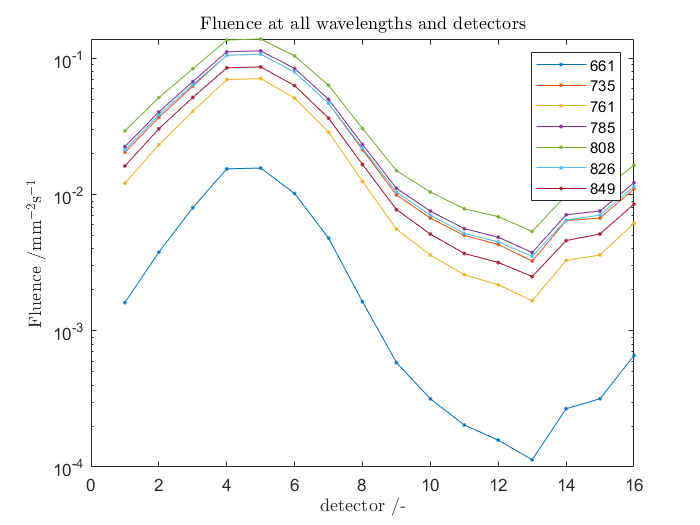


% boundary data
figure('Name',mesh.name)
semilogy(data_BLT.amplitude,'.-')
title('Fluence at all wavelengths and detectors','Interpreter','latex');
xlabel('detector /-','Interpreter','latex')
ylabel('Fluence /mm$^{-2}$s$^{-1}$','Interpreter','latex')
legend(num2str(mesh.wv))

## test BLT on 3D mesh:

% forward data 3D spectral data
mesh = load_mesh('cylinder_spec');

Fixed sources
Calculating sources integration functions
Fixed detectors
Calculating detectors integration functions



blob.x = 0;
blob.y = -10;
blob.z = -10;
blob.r = 10;
blob.region = 1;
mesh_anom = add_blob(mesh,blob);

Number of nodes modified = 140


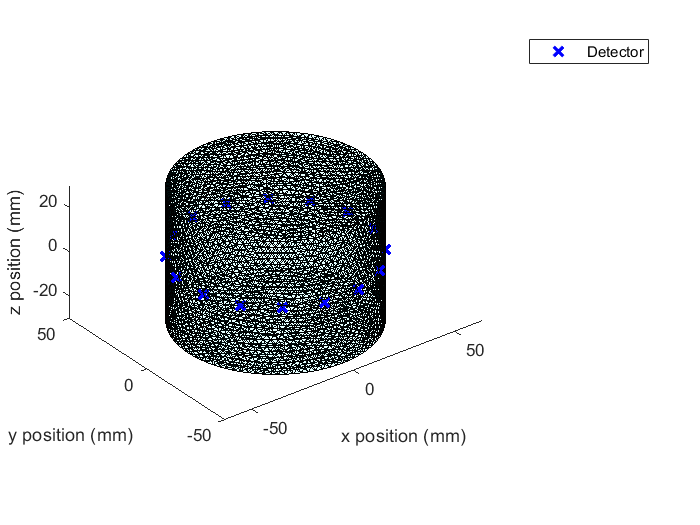

mesh.blt = mesh_anom.region;

% plot mesh with detectors only
mesh_anom = rmfield(mesh_anom,'source');
plotmesh_fiducials(mesh_anom);

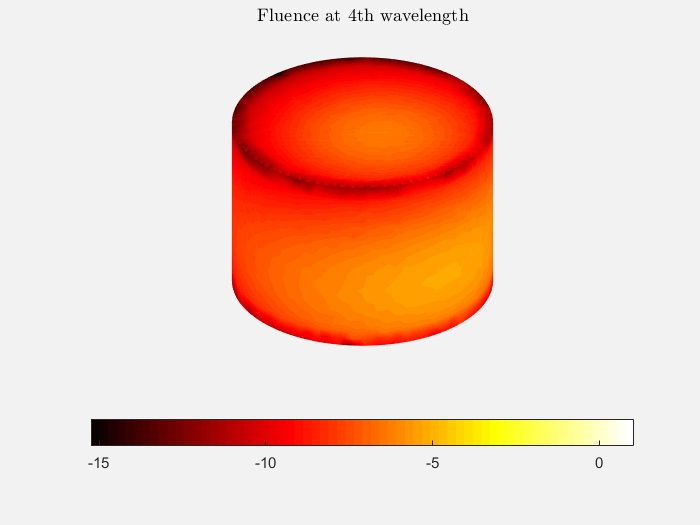


data_BLT = femdata_BLT(mesh);
plotimage(mesh,log(abs(data_BLT.phi(:,4))));
title('Fluence at 4th wavelength','Interpreter','latex');

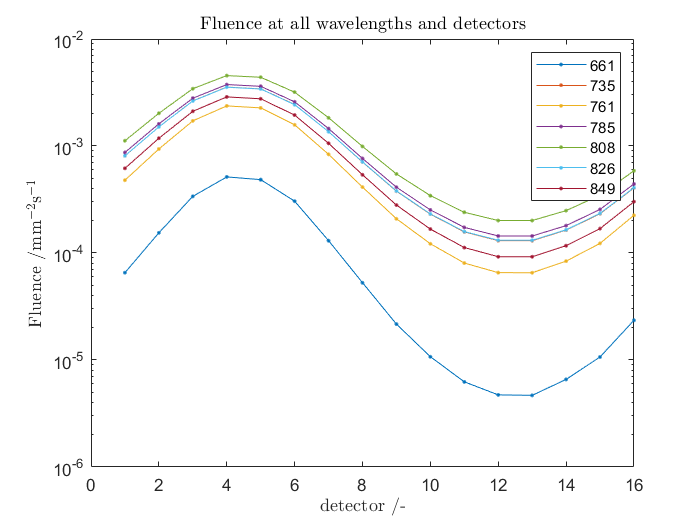


% boundary data
figure('Name',mesh.name)
semilogy(data_BLT.amplitude,'.-')
title('Fluence at all wavelengths and detectors','Interpreter','latex');
xlabel('detector /-','Interpreter','latex')
ylabel('Fluence /mm$^{-2}$s$^{-1}$','Interpreter','latex')
legend(num2str(mesh.wv))